# Mugnolo's First Example

## A balalaika-shaped graph

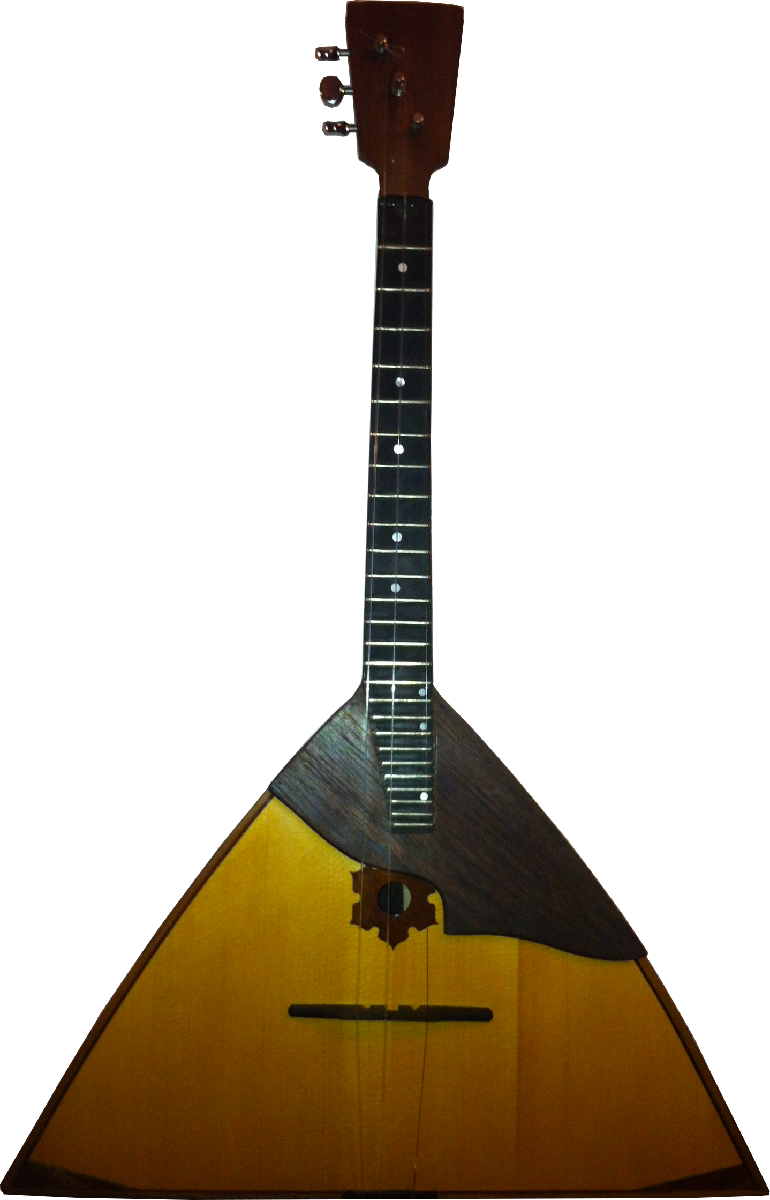

L = [3 4 sqrt(10) pi];
numEigs=6;

## The basic graph

Calculate and display the first few eigenvalues and eigenfunctions;

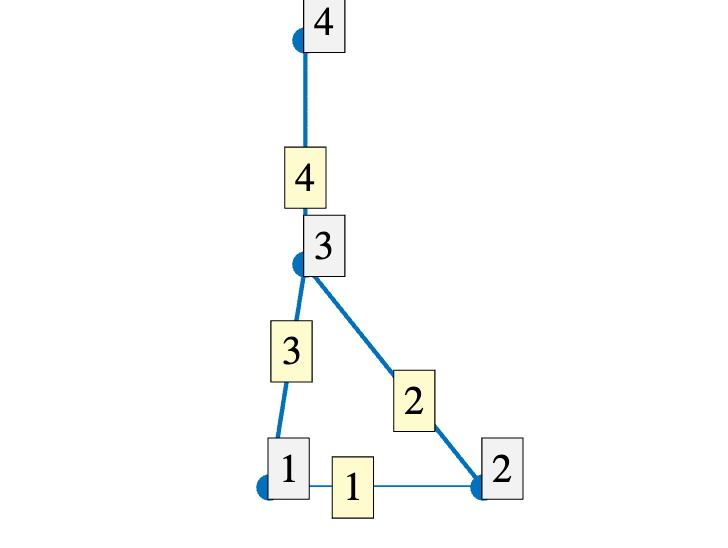

Phi1= quantumGraphFromTemplate('balalaika',Lvec=L,discretization='Chebyshev');
Phi1.plot('layout');

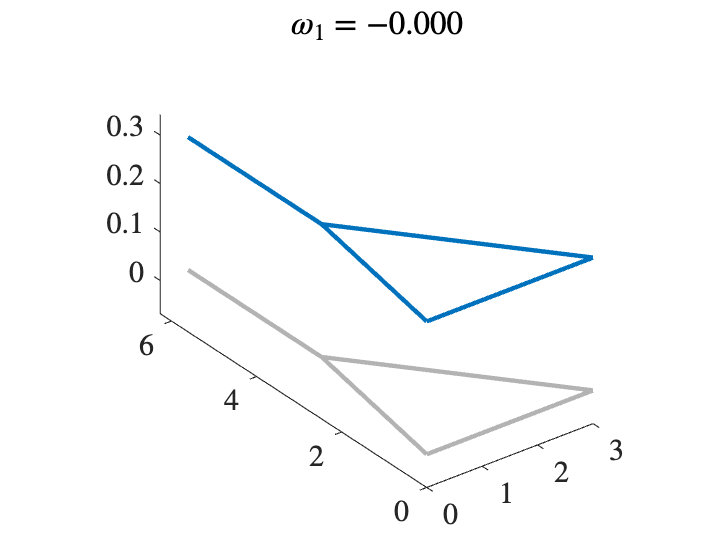

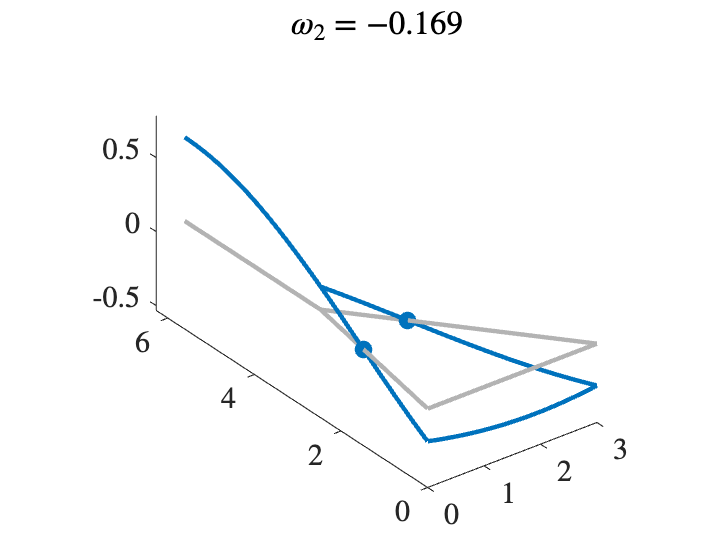

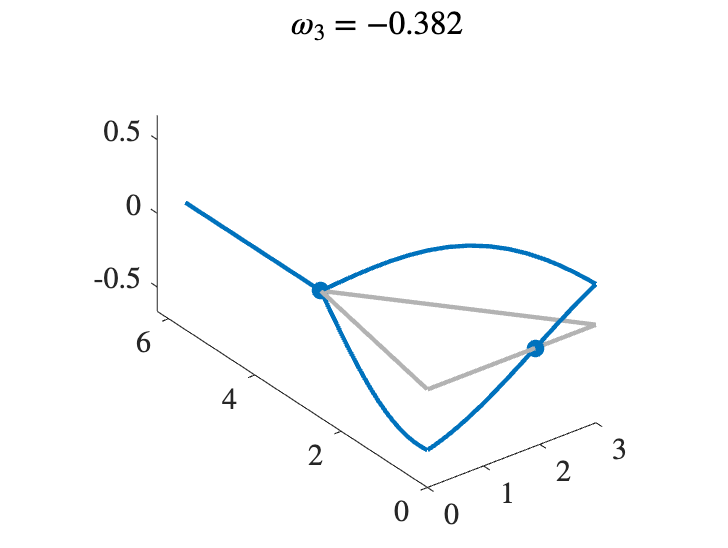

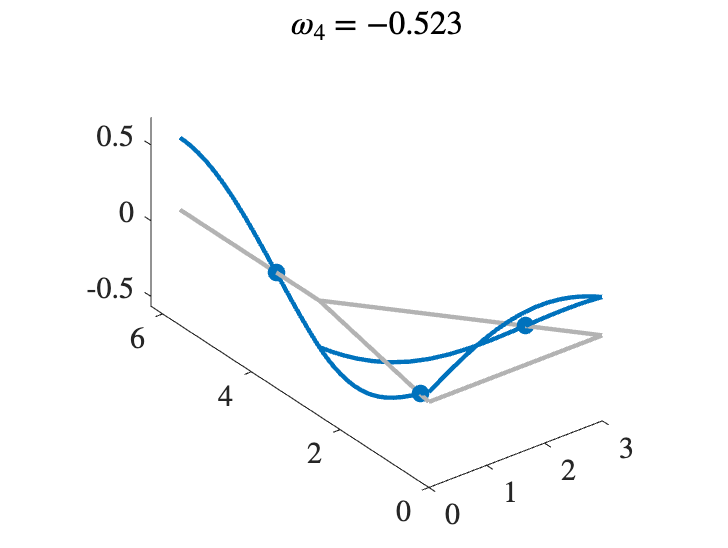

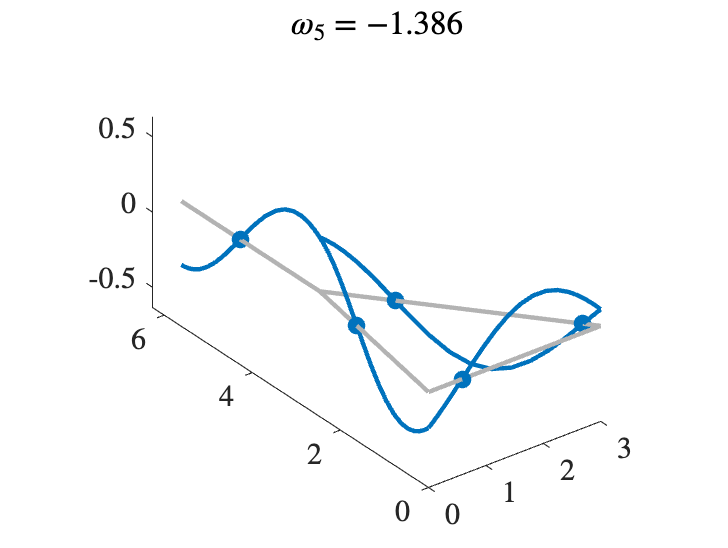

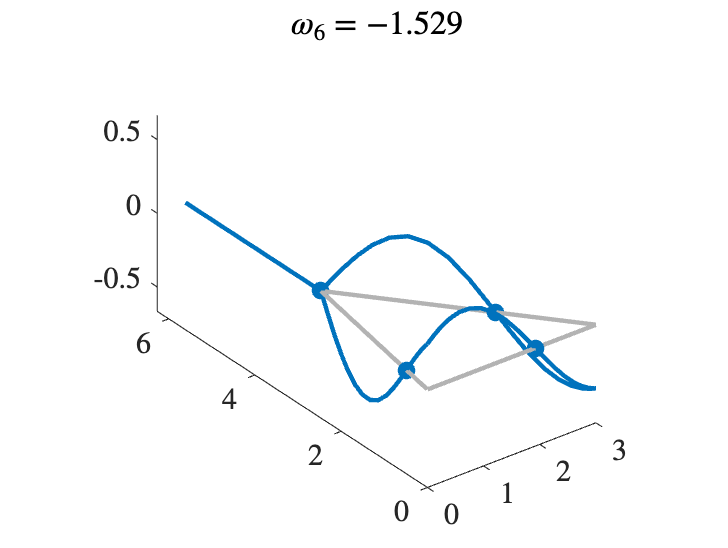

[V1,d1]=Phi1.eigs(numEigs);
for k=1:numEigs
    figure
    Phi1.plot(V1(:,k));
    title(sprintf('$\\omega_{%i} = %0.3f$',k,d1(k)))
end

## The graph with edges doubled

Note all the first 4 eigenvalues and eigenvectors are unchanged but numbers 5 and 6 feature split edges and smaller frequencies

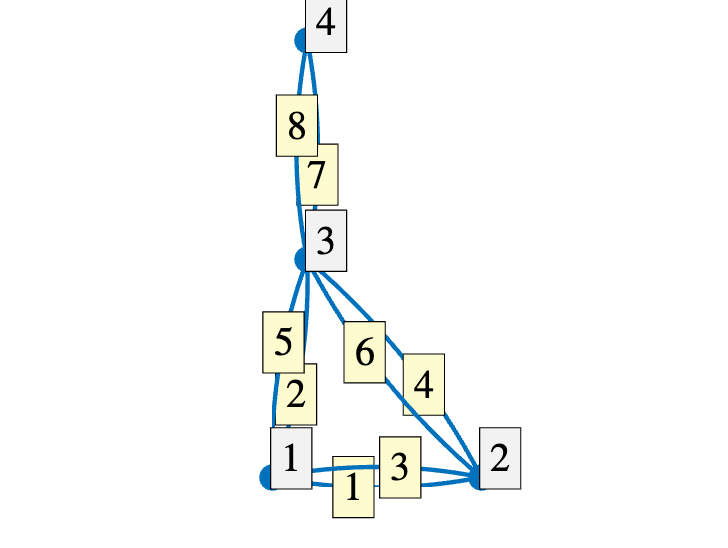

Phi2= quantumGraphFromTemplate('balalaikaDoubled',Lvec=L,discretization='Chebyshev');
Phi2.plot('layout');

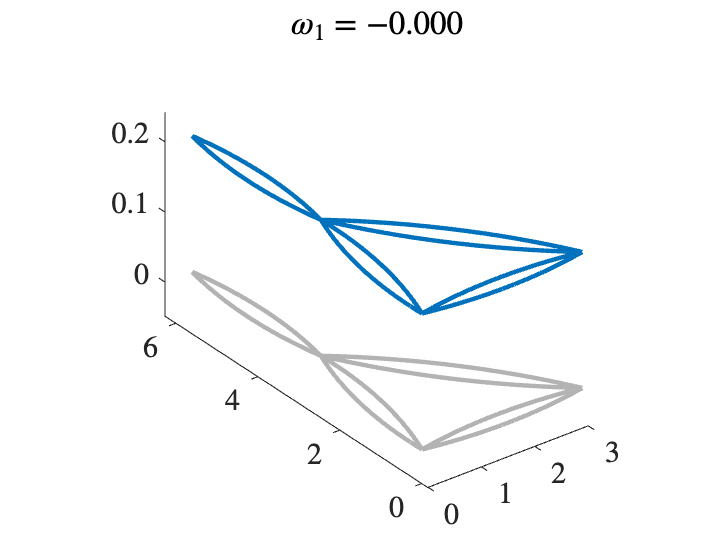

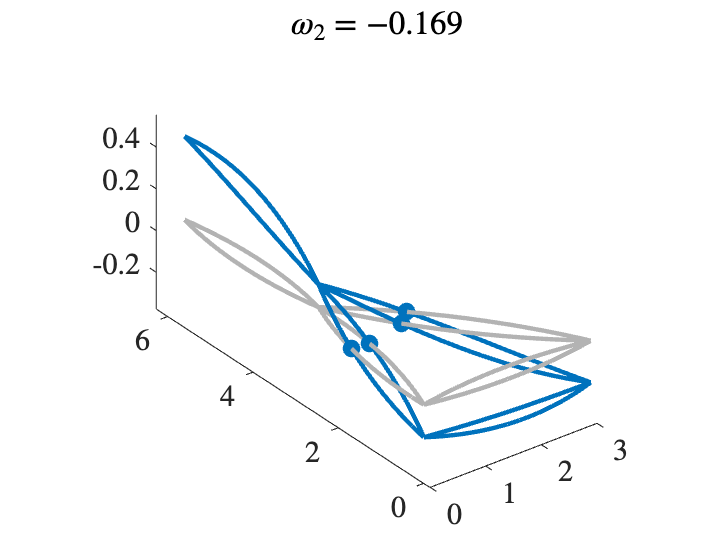

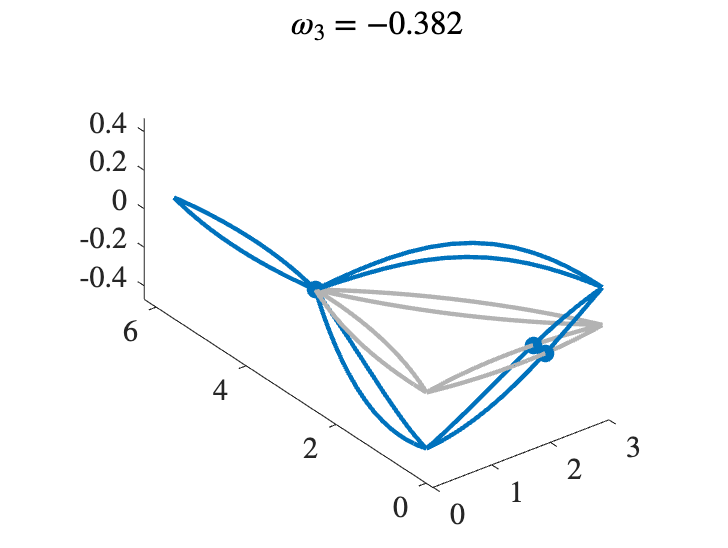

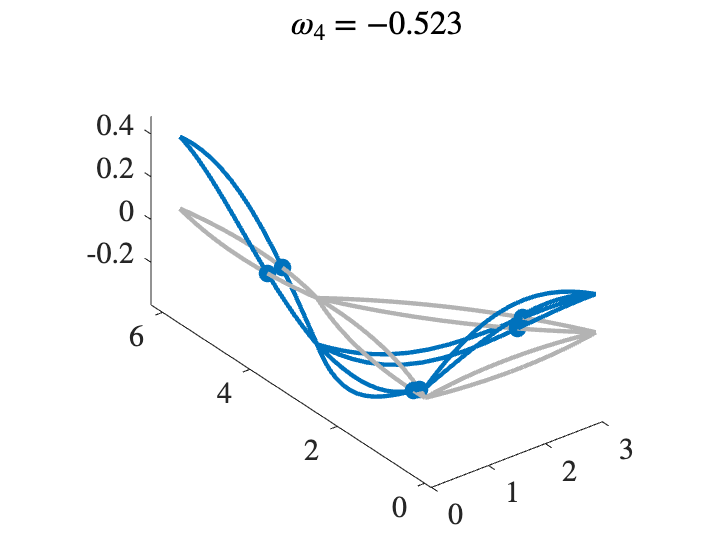

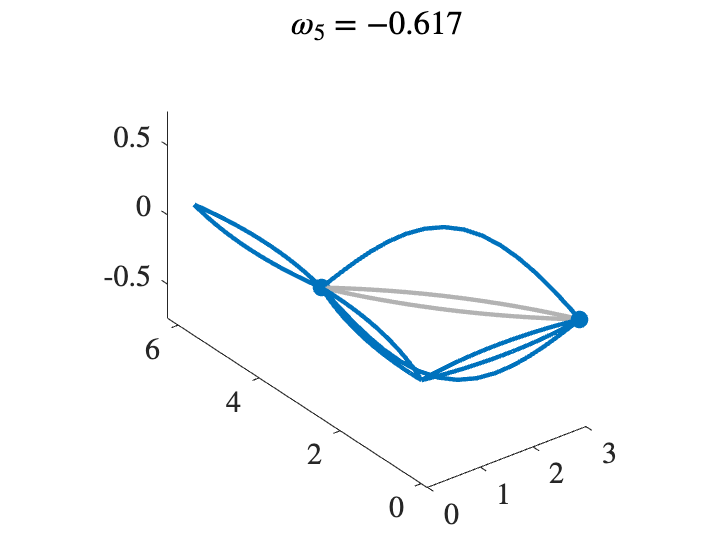

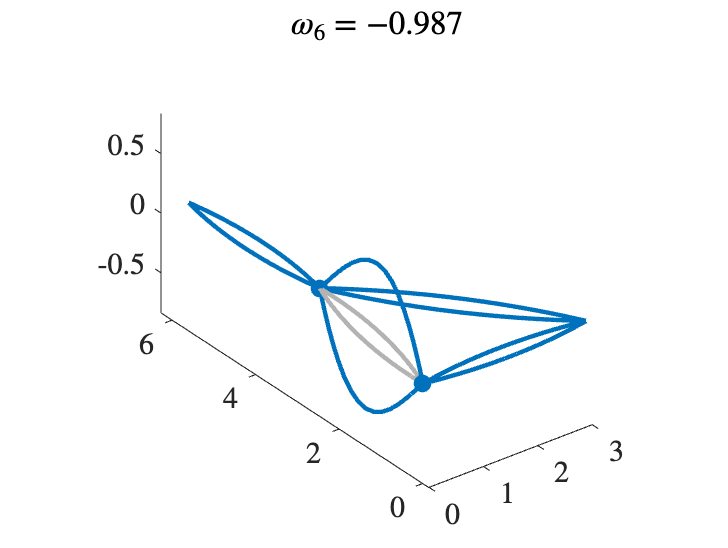

[V2,d2]=Phi2.eigs(numEigs);
for k=1:numEigs
    figure
    Phi2.plot(V2(:,k));
    title(sprintf('$\\omega_{%i} = %0.3f$',k,d2(k)))
end

## The previous graph split at the vertices

All the frequencies are smaller

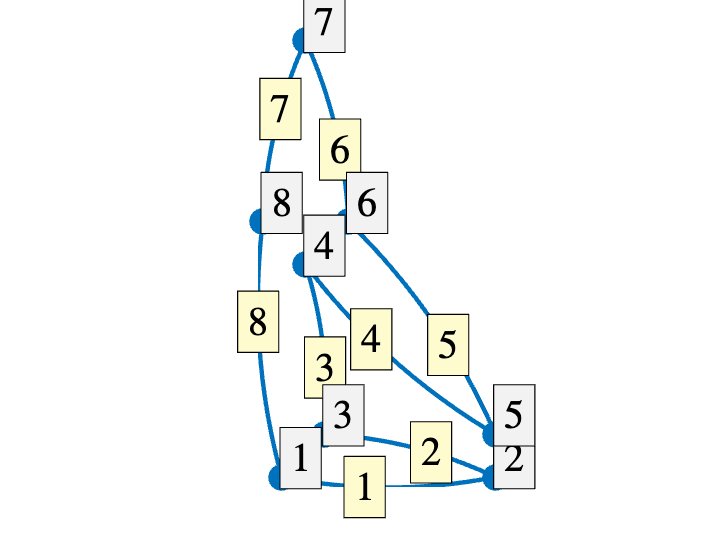

Phi3= quantumGraphFromTemplate('balalaikaBroken',Lvec=L,discretization='Chebyshev');
Phi3.plot('layout');

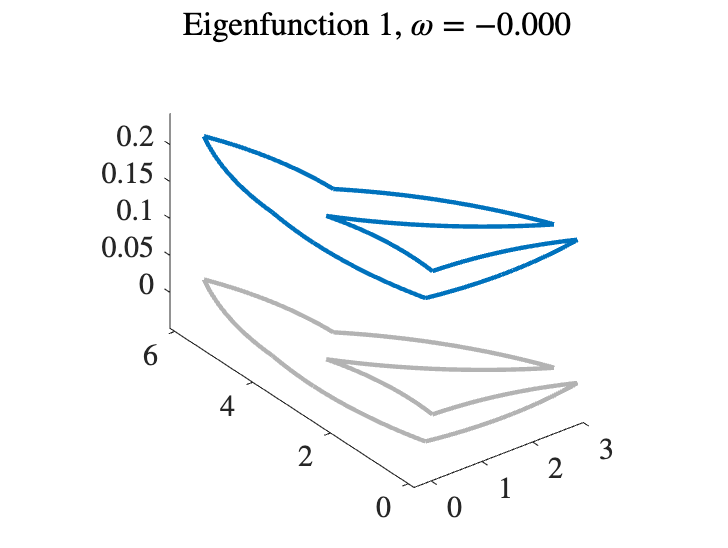

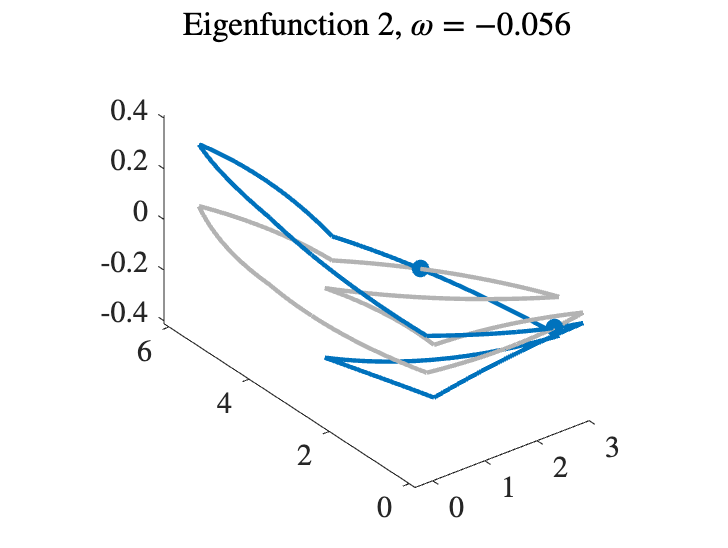

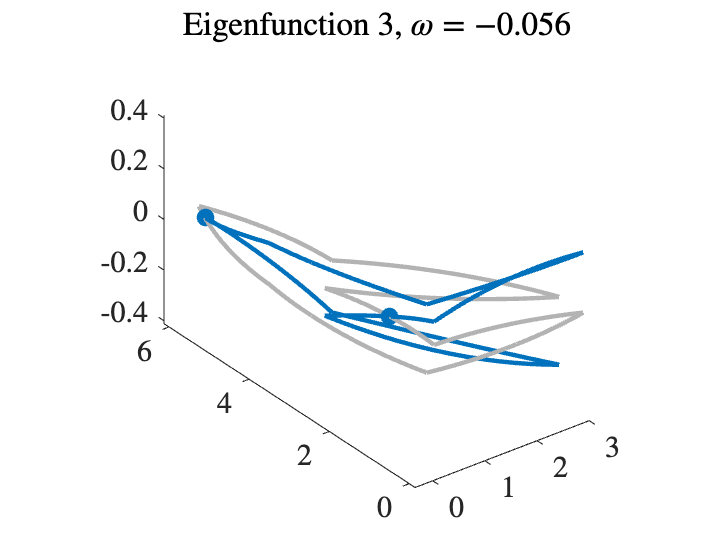

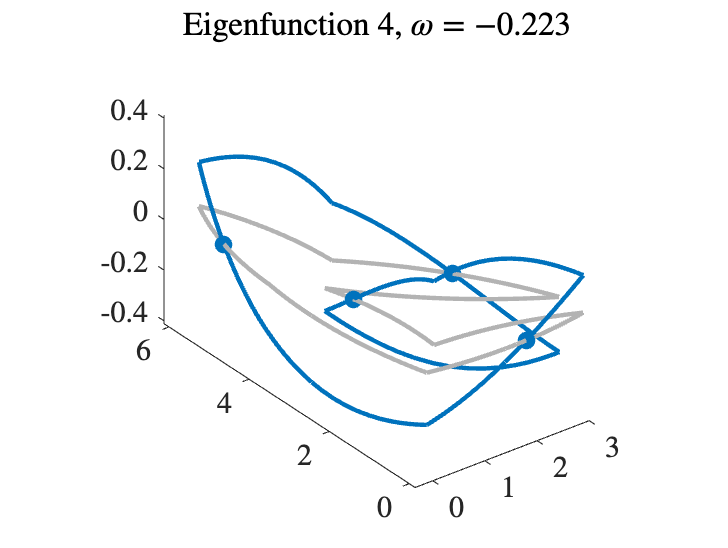

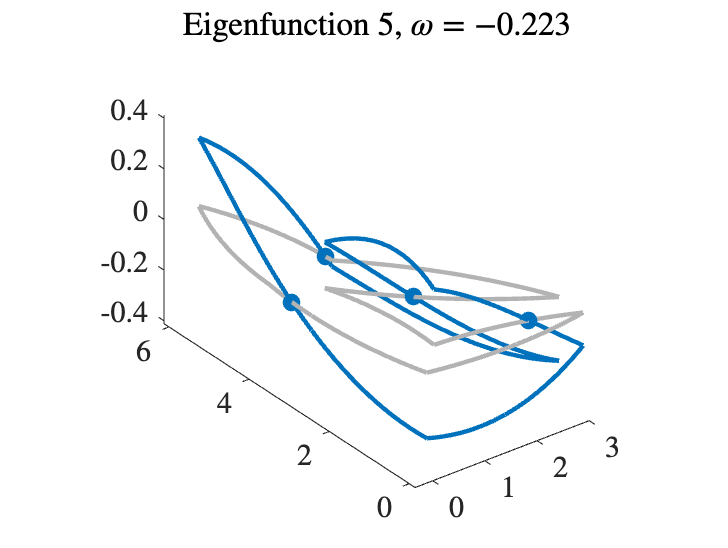

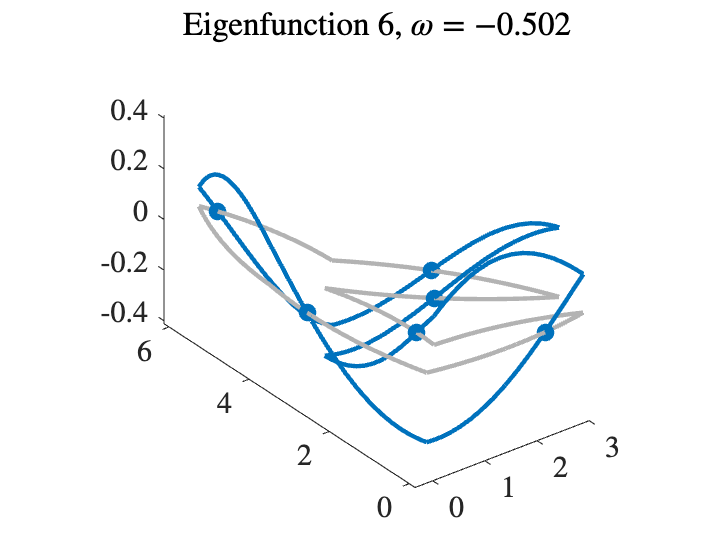

[V3,d3]=Phi3.eigs(numEigs);
for k=1:numEigs
    figure
    Phi3.plot(V3(:,k));
    title(sprintf('Eigenfunction %i, $\\omega = %0.3f$',k,d3(k)))
end

## Comparing the frequencies

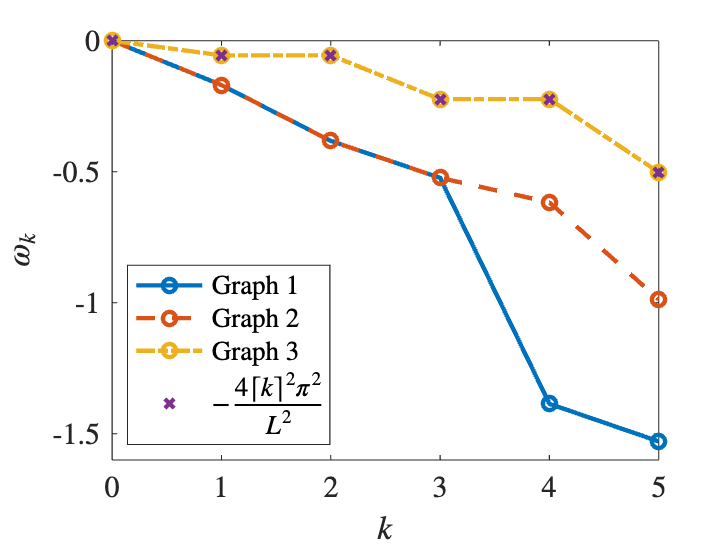

Ltotal = 2*sum(L);
nn = 0:numEigs-1;
w= -ceil(nn/2).^2*4*pi^2/Ltotal^2;
plot(nn,d1,'-o',nn,d2,'--o',nn,d3,'-.o',nn,w,'x')
exactString=('$-\frac{4 \lceil k\rceil^2\pi^2}{L^2}$');
xlabel('$k$')
ylabel('$\omega_k$')
legend('Graph 1','Graph 2','Graph 3',exactString,'Location','southwest')